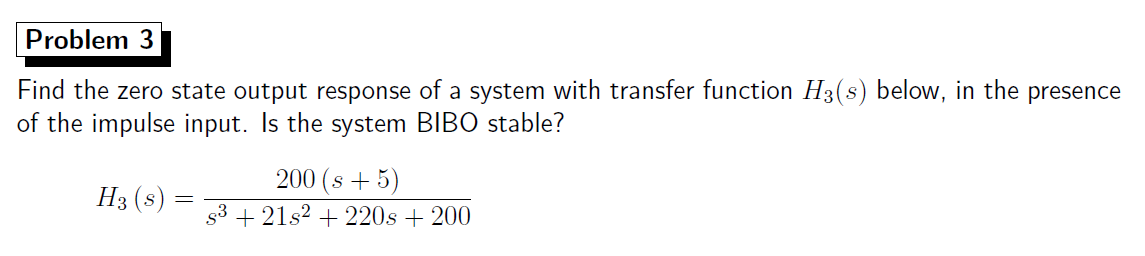

syms t f H s

H=200*(s+5)/(s^3+21*s^2+220*s+200)

$$H = \frac{200\,s+1000}{s^{3}+21\,s^{2}+220\,s+200}$$

f(t)=piecewise(t<0, 0,t==0,100000,t>0,0)

$$f(t) = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 100000 & \text{ if }t=0\\ 0 & \text{ if }0<t \end{array}\right.$$

y=vpa(simplify(ilaplace(laplace(f)*H),'Steps',1000),4)

$$y = 1000.0\,\mathrm{ilaplace}\left(\frac{\mathrm{laplace}\left(\left\{ \begin{array}{cl} 100000 & \text{ if }t=0\\ 0 & \text{ if }t\neq 0 \end{array}\right.,t,s\right)}{\left(s+1\right)\,\left(s^{2}+20\,s+200\right)},s,t\right)+200.0\,\mathrm{ilaplace}\left(\frac{s\,\mathrm{laplace}\left(\left\{ \begin{array}{cl} 100000 & \text{ if }t=0\\ 0 & \text{ if }t\neq 0 \end{array}\right.,t,s\right)}{\left(s+1\right)\,\left(s^{2}+20\,s+200\right)},s,t\right)$$



% simulink;
% sim("ex3.slx");
% out.ZeroStateOutput

## Control Toolbox

clear
s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



H=200*(s+5)/(s^3+21*s^2+220*s+200)

H =
 
         200 s + 1000
  --------------------------
  s^3 + 21 s^2 + 220 s + 200
 
Continuous-time transfer function.




H=minreal(zpk(H))  %zero pole gain model to see immediately the poles(zeros of denominator) and the zeros

H =
 
         200 (s+5)
  -----------------------
  (s+1) (s^2 + 20s + 200)
 
Continuous-time zero/pole/gain model.



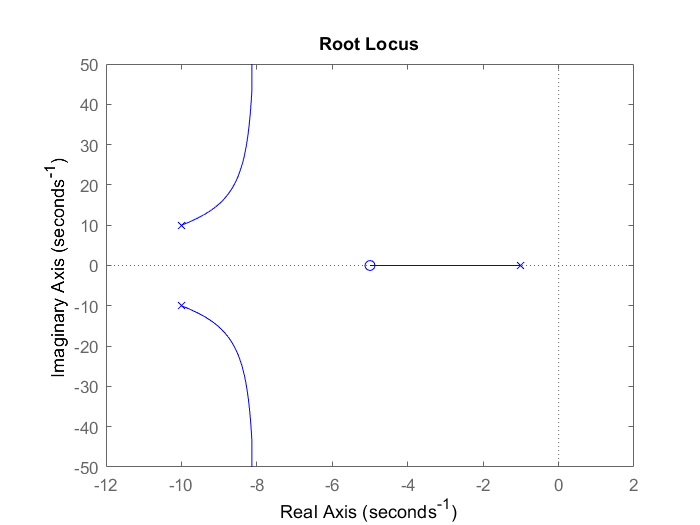

rlocus(H,'b')



pole(H)

ans =  -10.0000 +10.0000i
 -10.0000 -10.0000i
  -1.0000 + 0.0000i


Looking at the poles The system is BIBO stable.